# Diffraktion

## Fresnel

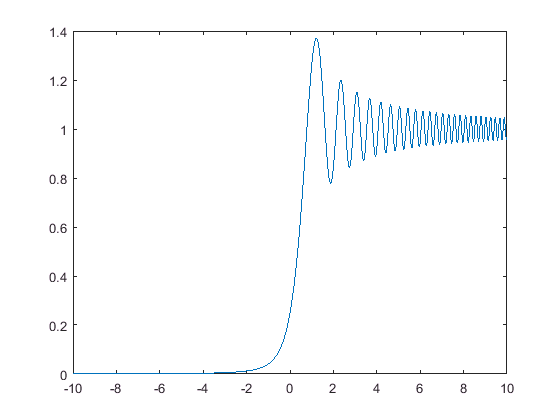

%p = 0.01;
%q = 0.686;
%L = 1/(1/p + 1/q);
%lambda = 404e-9;
%screenSize = 0.034;

p = 1;
q = 1;
L = 1/(1/p + 1/q);
lambda = 1;
screenSize = 20;

y = linspace(-screenSize/2,screenSize/2,1001);

z = y*p/(q + p);

v = z*sqrt(2/(L*lambda));

intensity = ((0.5 - fresnelc(-v)).^2 + (0.5 - fresnels(-v)).^2)/2;

plot(y, intensity);

## Fraunhofer

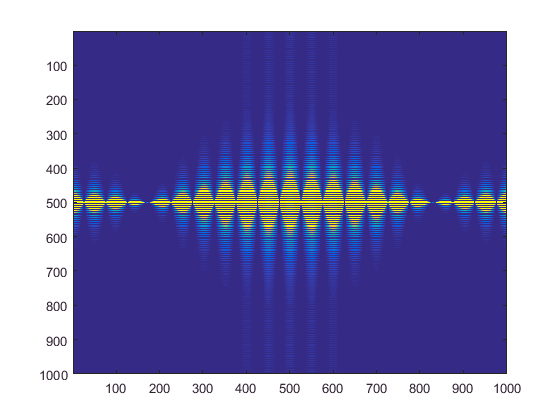

resolution = 1000;
Nx = resolution/1000;
Ny = resolution/4;
d = resolution/50;
slit = zeros(resolution);
slit(resolution/2-Ny:resolution/2+Ny,resolution/2-Nx-d/2:resolution/2+Nx-d/2) = 1;
slit(resolution/2-Ny:resolution/2+Ny,resolution/2-Nx+d/2:resolution/2+Nx+d/2) = 1;
diff = fftshift(fft2(slit));
image(abs(diff).^2/10);

## Spaltsystem

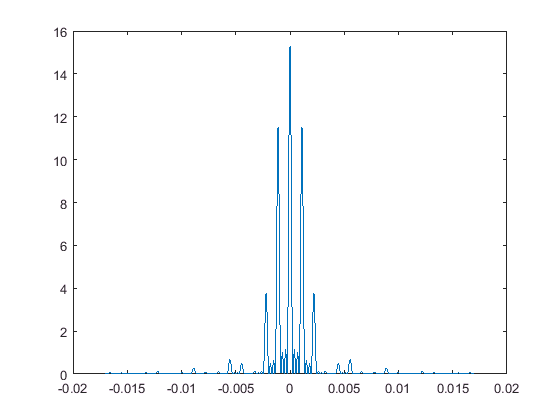

L = 0.686;
lambda = 404e-9;
screenSize = 0.034;
d = 0.25e-3;
b = 0.077e-3;
N = 4;

y = linspace(-screenSize/2,screenSize/2,1001);

theta = y/L;
%theta = atan(theta);

beta = 1/lambda*b*sin(theta);
gamma = beta*pi*d/b;

plot(y, (sinc(beta).*sin(N*gamma)./(sin(gamma))).^2);

## Babinet

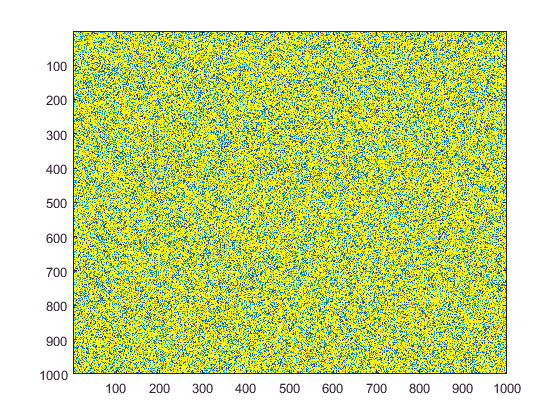

resolution = 1000;
Nx = resolution/100;
Ny = resolution/100;
%slit = zeros(resolution);
%slit(resolution/2-Ny:resolution/2+Ny,resolution/2-Nx:resolution/2+Nx) = 1;
slit = floor(1.001*rand(resolution));
diff1 = fftshift(fft2(slit));
image(abs(diff1).^2/10);

diff2 = fftshift(fft2(1 - slit));
image(abs(diff2).^2/10);

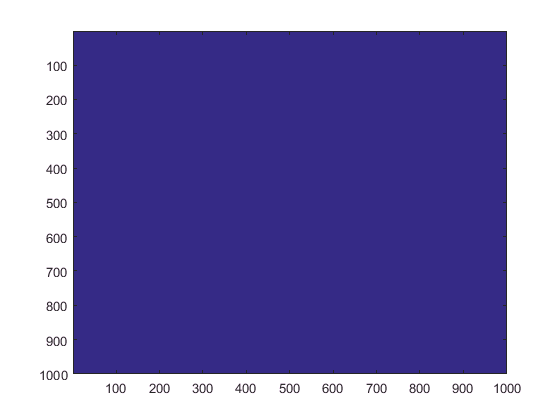

image(abs(diff1 + diff2).^2/10);